# DC motor speed control: state space

The state variables are theta_dot and the current i, with input V, so that the state space equation is


$$\begin{array}{l}
\left\lbrack \begin{array}{c}
\theta^¨ \\
\dot{i} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
-\frac{b}{J} & \frac{K}{J}\\
-\frac{K}{L} & \frac{R}{L}
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\theta^˙ \;\\
i
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
1
\end{array}\right\rbrack V\\
y=\left\lbrack 1\;0\right\rbrack \left\lbrack \begin{array}{c}
\theta^˙ \\
i
\end{array}\right\rbrack 
\end{array}$$


## System setup

J = 0.01;
b = 0.1;
K = 0.01; %notice this k
R = 1;
L = 0.5;
A = [-b/J   K/J; -K/L   -R/L];
B = [0; 1/L];
C = [1 0];
D = 0;
sys = ss(A,B,C,D);

## Check controllability

% ctrb(A, B);

## Full-state feedback design

s1 = -5 + 1i;
s2 = -5 - 1i;
k_gain = place(A, B, [s1, s2]);

## Input rescaling

sys_cl = ss(A-B*k_gain,B,C,D);
rscale = 1/dcgain(sys_cl);
step(rscale*sys_cl)

Note: if one uses "feedback" command

% sys.C = eye(2);


sys_cl =
 
  A = 
               x1          x2          x3          x4
   x1         -10           1           0           0
   x2         -26  -1.332e-15           0           0
   x3           0           0         -10           1
   x4           0           0         -26  -1.332e-15
 
  B = 
       u1
   x1   0
   x2   2
   x3   0
   x4   2
 
  C = 
        x1   x2   x3   x4
   y1    1    0    0    0
   y2    0    0    0  1.3
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.



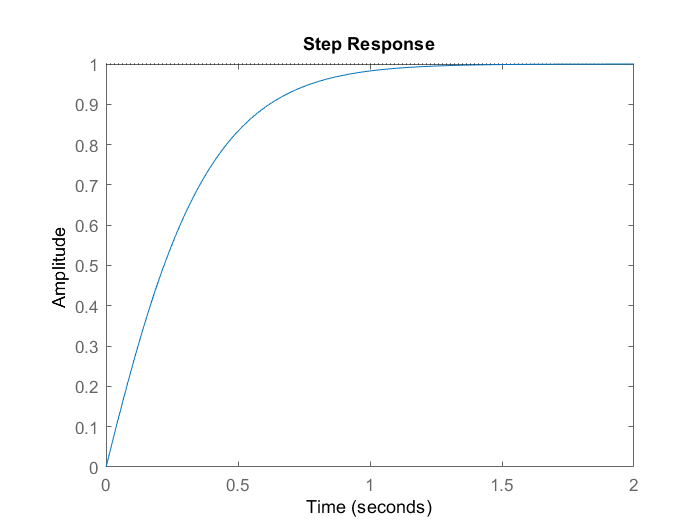

% sys_cl = feedback(sys, k_gain);

% rscale = 1/dcgain(sys_cl(2));
% sys_cl(2) = rscale * sys_cl(2)
% step(sys_cl(2));